# Comparing two sources of blur: Pinholes and Diffraction

Consider how much blur we would have for each point of light if we are creating an image of the scene through a pinhole, as in the Ayscough painting (Figure XX).

The size of the pinhole determines one type of blur. As the pinhole gets larger, each point will be spread by an amount roughly equal to the pinhole size.  Let's choose some pinhole sizes here.  We specify their diameters ranging from about 10 microns to 1.2mm.  And let's pick a wavelength of the light.

pinholeD = (100:100:2000)*1e-6;   % Pinhole diameter (meters)

wave = 400e-9;                  % Wavelength (meters)

Airy's formula for the image we expect to find from waves passing through a circular pinhole can be calculated using ISETCam. Notice that there is a big central peak (the Airy disk) and then a series of ripples separated by zero-crossings.

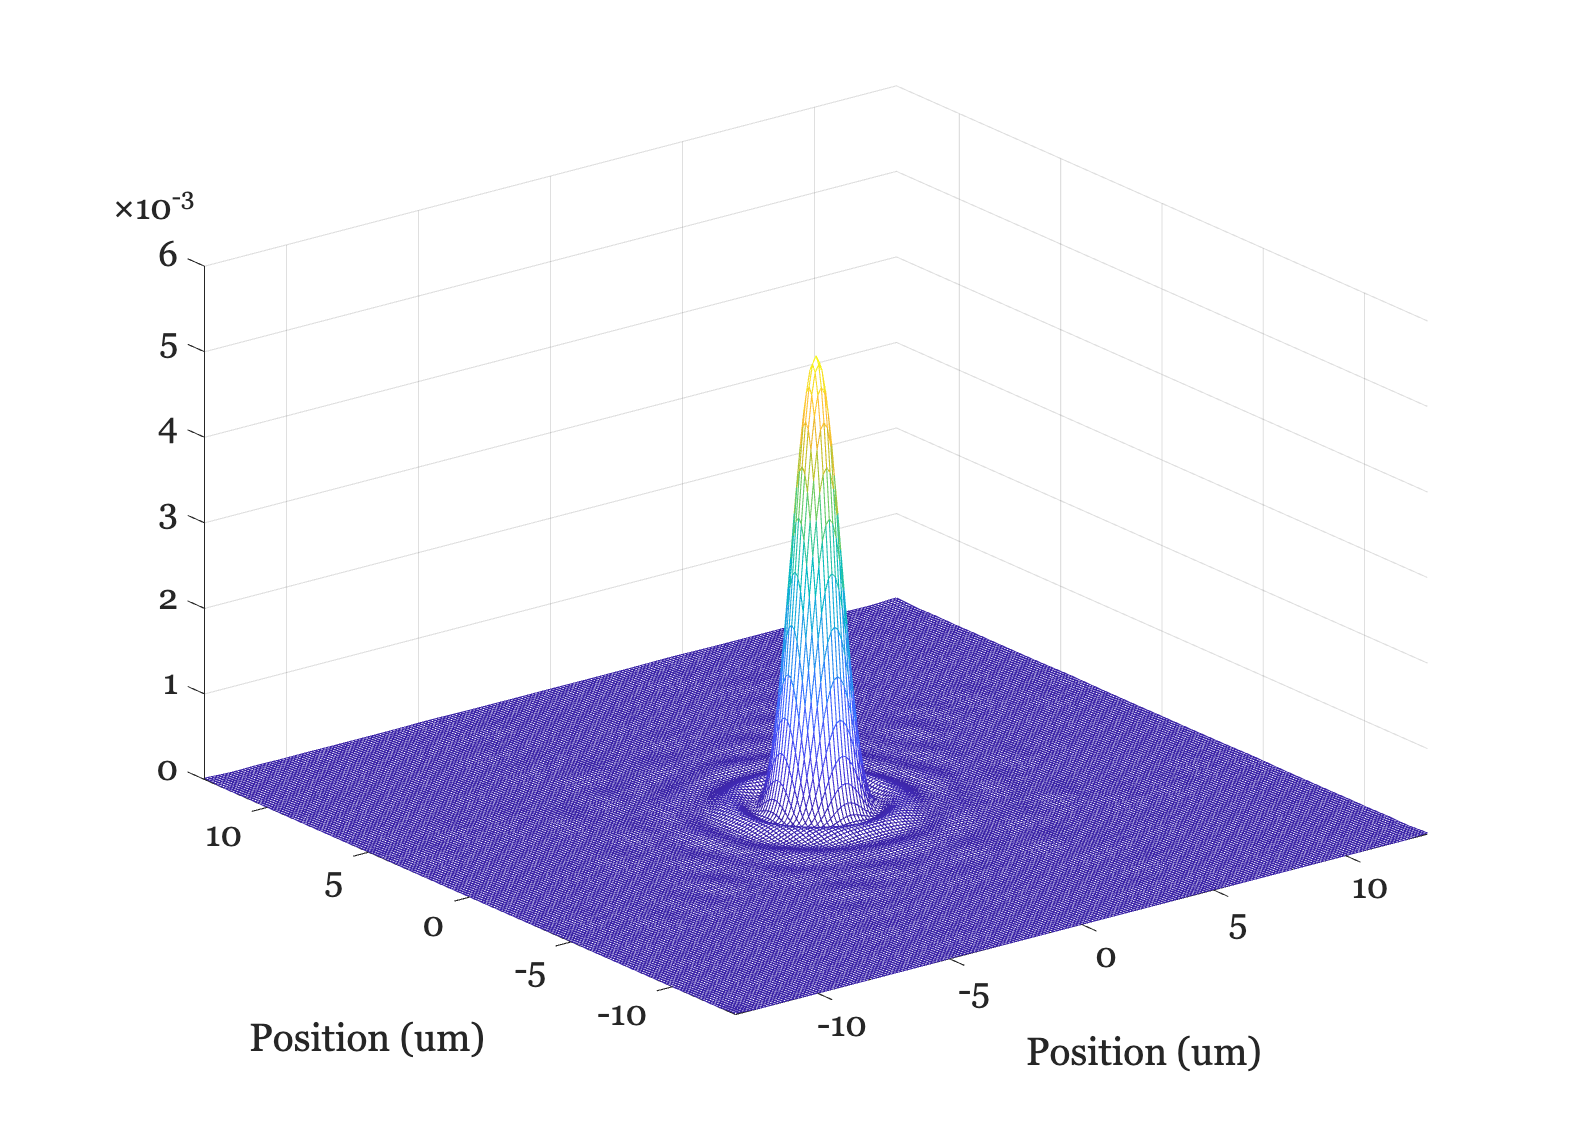

fNumber = 5;   % Longer wavelength
[~,img] = airyDisk(wave,fn,'units','um');
ieNewGraphWin; mesh(img.x,img.y,img.data); xlabel('Position (um)'); ylabel('Position (um)');

## Plot the Airy disk diameter and pinhole size

There is a simple formula for the first zero-crossing.  It is given here in terms of degrees of spread for the rays coming out of the pinhole.  That way we can calculate the size of the spread when we know the distance to the wall.

IMAGE HERE SHOWING PINHOLE AND ANGLE

%  Airy disk radius (meters)
diffractionDeg = asind(1.22*(wave ./ pinholeD));
% Radius size on a wall, L meters away
L = 1;   

% tand(theta) = opp/adj;
diffractionD = 2*L*tand(diffractionDeg);


This graph plots the spread from diffraction as a function of pinhole diameter (red line).  We also show the size of the pinhole as the identity line.  Where the two lines intersect is where the spread from diffraction equals the spread from the pinhole.  Notice that when the wall is 1 meter away, and the pinhole is a little less than 1 mm, the spread from diffraction and from the pinhole blur are about equal.

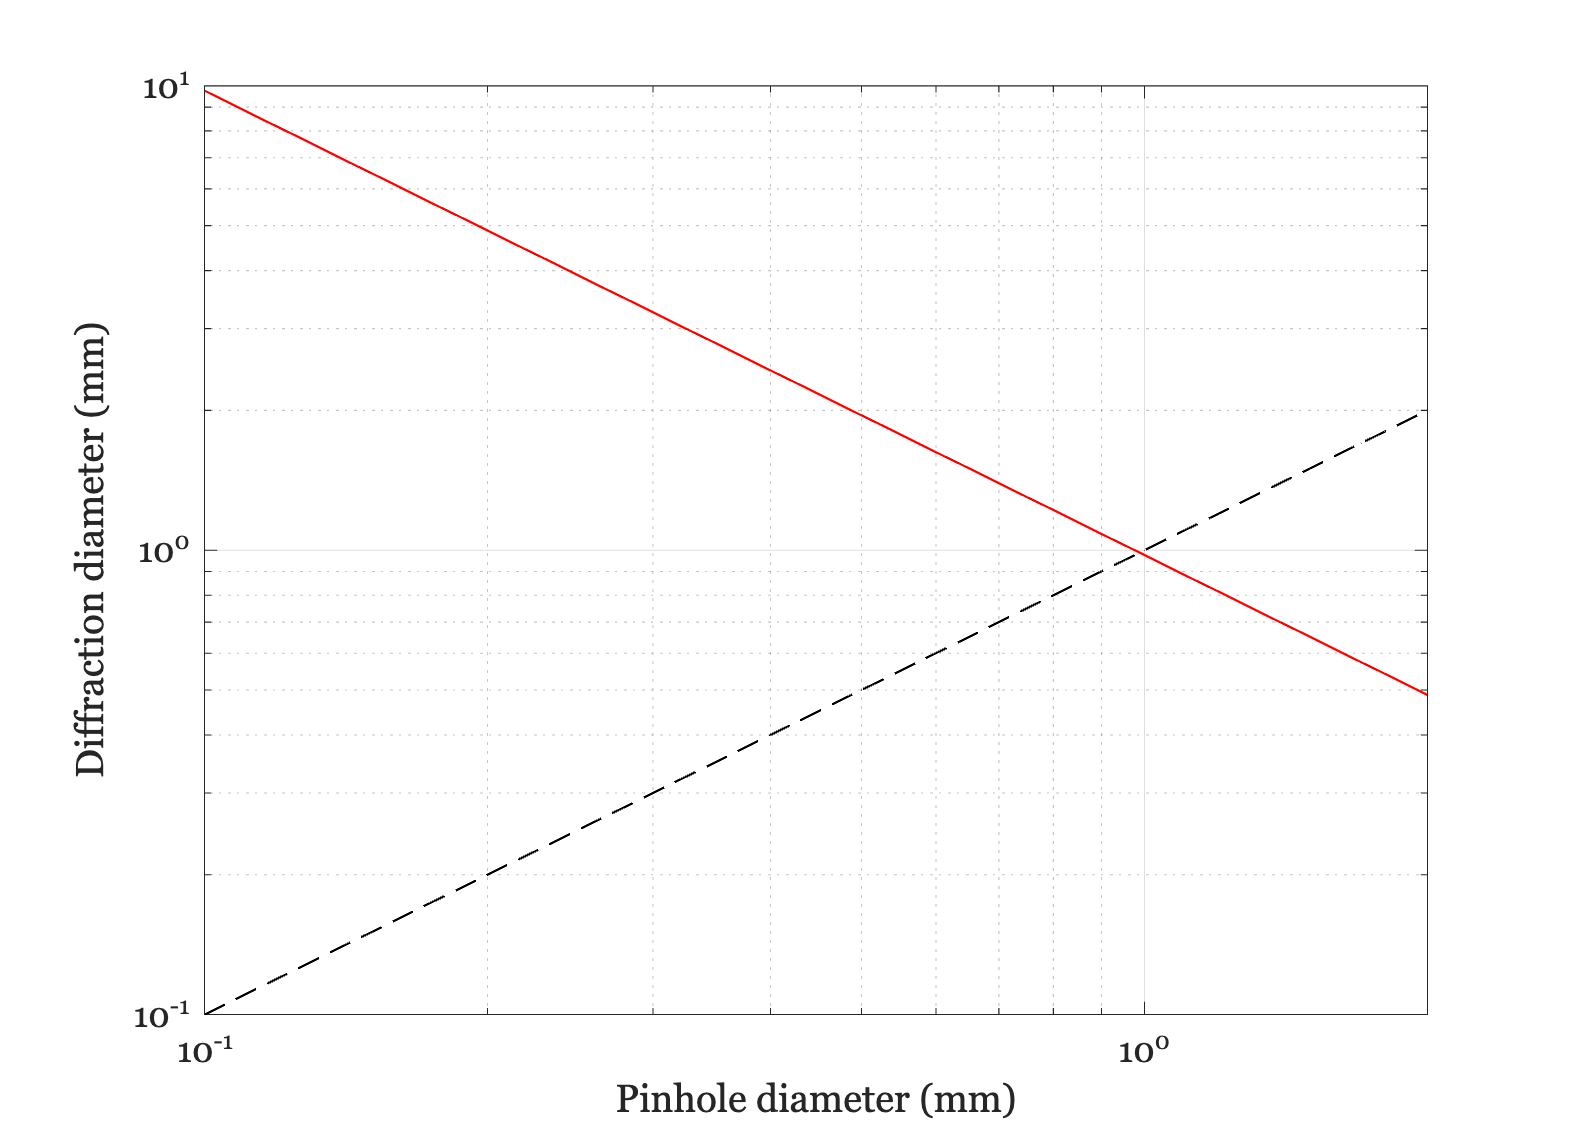

ieNewGraphWin;
unit = 'mm';
loglog(pinholeD*ieUnitScaleFactor(unit),diffractionD*ieUnitScaleFactor(unit),'-');
hold on;
loglog([0;pinholeD(:)]*ieUnitScaleFactor(unit),[0;pinholeD(:)]*ieUnitScaleFactor(unit),'k--');
xlabel(sprintf('Pinhole diameter (%s)',unit));
ylabel(sprintf('Diffraction diameter (%s)',unit));
grid on;

## How does this depend on the distance to the wall?

Let's plot the same graph but for some different parameters.

ieNewGraphWin;
unit = 'mm';

% Distances are 5, 50 and 500 millimeters
pinholeD = (10:10:1200)*1e-6;   % Pinhole diameter (meters)
diffractionDeg = asind(1.22*(wave ./ pinholeD));

Lmeters = logspace(log10(0.001),log10(1),3);
match = zeros(size(Lmeters));

for ii=1:numel(Lmeters)
    % Radius size on a wall, L meters away
    L = Lmeters(ii);
    diffractionD = 2*L*tand(diffractionDeg);
    p = loglog(pinholeD*ieUnitScaleFactor(unit),diffractionD*ieUnitScaleFactor(unit),'-');
    hold on;
    % p.Color = [0 0 0];
    [v,idx] = min(abs(pinholeD - diffractionD));
    match(ii) = pinholeD(idx)*ieUnitScaleFactor(unit);
    fprintf('L = %f (m): Equal blur %f (%s)\n',Lmeters(ii),match(ii),unit);
end

L = 0.001000 (m): Equal blur 0.030000 (mm)
L = 0.031623 (m): Equal blur 0.180000 (mm)
L = 1.000000 (m): Equal blur 0.990000 (mm)


Notice that as the wall gets closer to the pinhole, the diffraction blur shrinks and the size of the pinhole that matches the diffraction blur shrinks as well.  Also, notice that this axis is loglog!

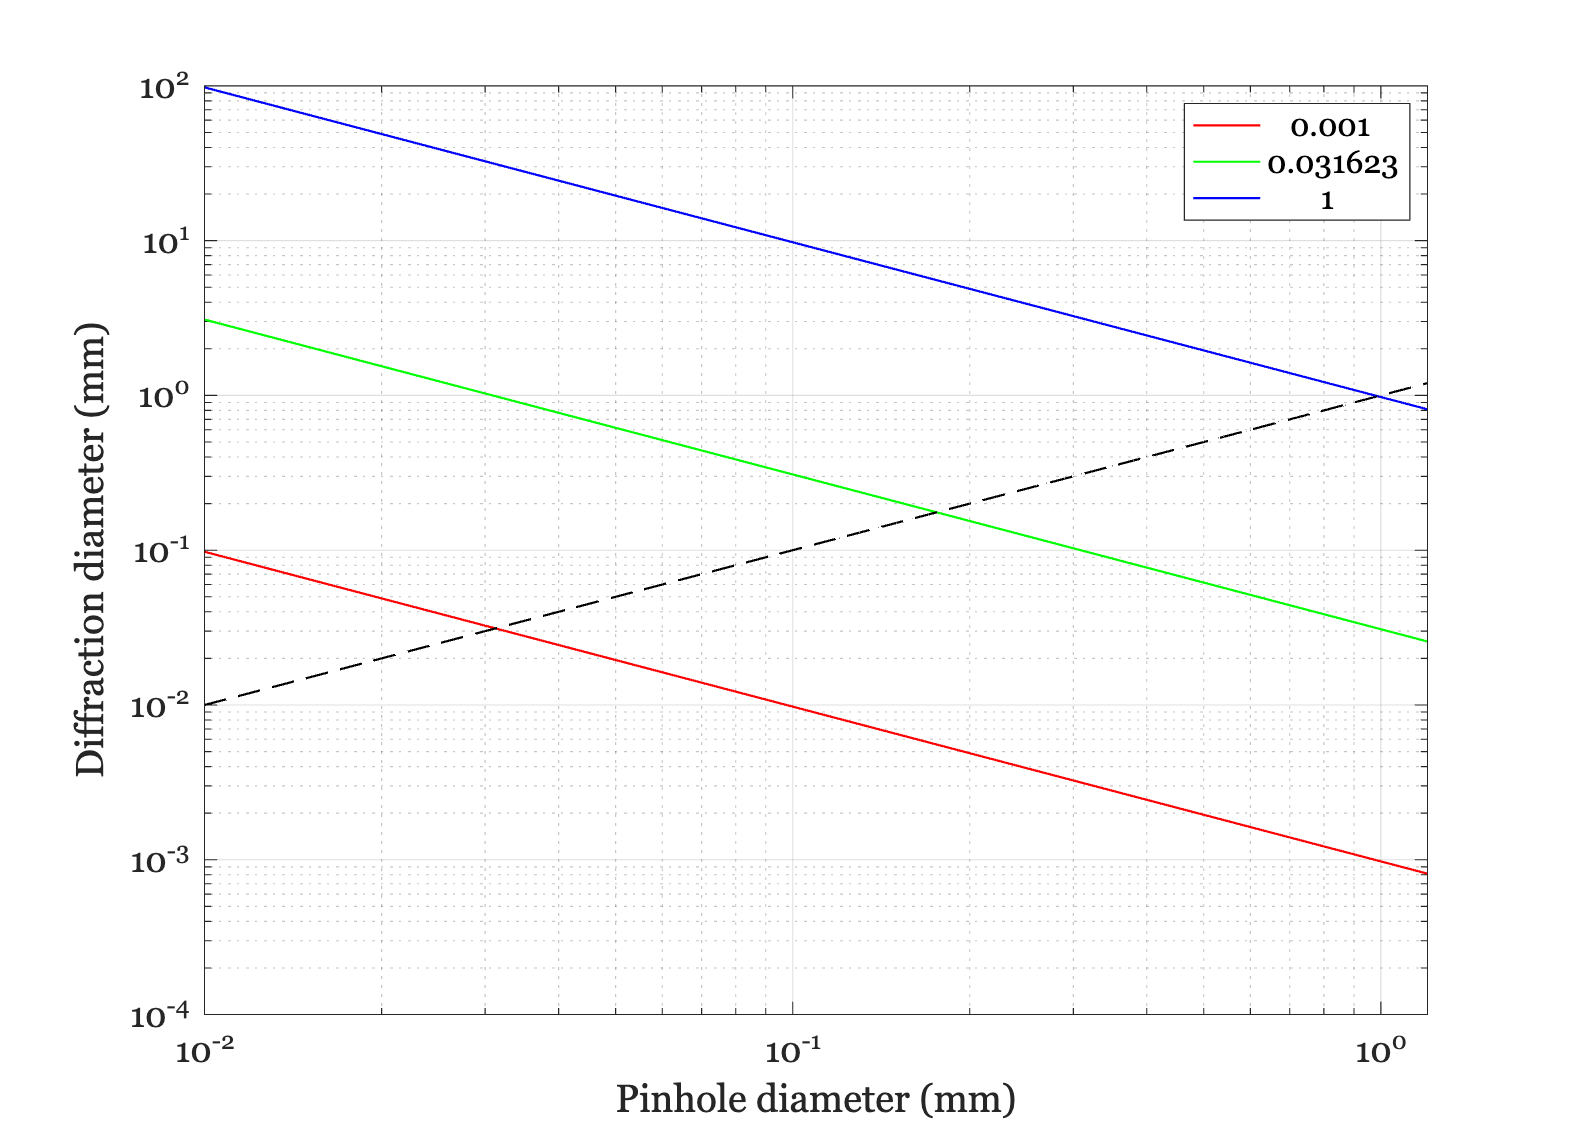

xlabel(sprintf('Pinhole diameter (%s)',unit));
ylabel(sprintf('Diffraction diameter (%s)',unit));
loglog([0;pinholeD(:)]*ieUnitScaleFactor(unit),[0;pinholeD(:)]*ieUnitScaleFactor(unit),'k--');
grid on;
legend(num2str(Lmeters(:)))